OTRO EJ8

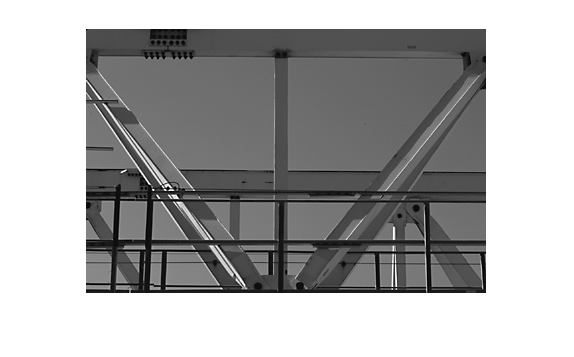

RGB = imread('gantrycrane.png');
I  = rgb2gray(RGB);
rotI = imrotate(I,0,'crop');
imshow(rotI)

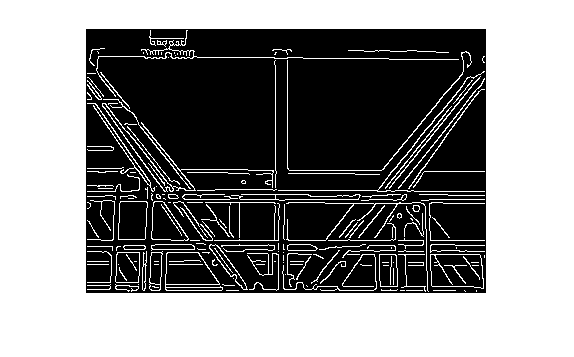

BW = edge(rotI,'canny');
imshow(BW);

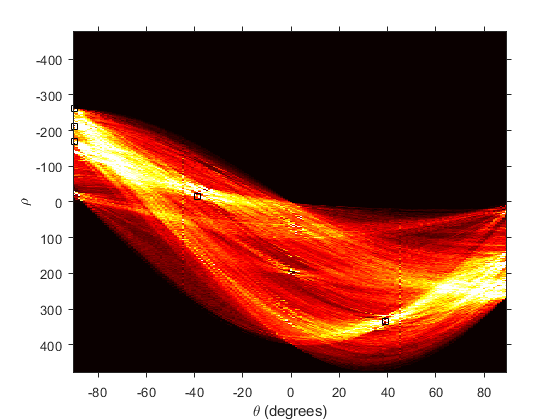

[H,theta,rho] = hough(BW);
figure
imshow(imadjust(rescale(H)),[],...
       'XData',theta,...
       'YData',rho,...
       'InitialMagnification','fit');
xlabel('\theta (degrees)')
ylabel('\rho')
axis on
axis normal 
hold on
colormap(gca,hot)
P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');

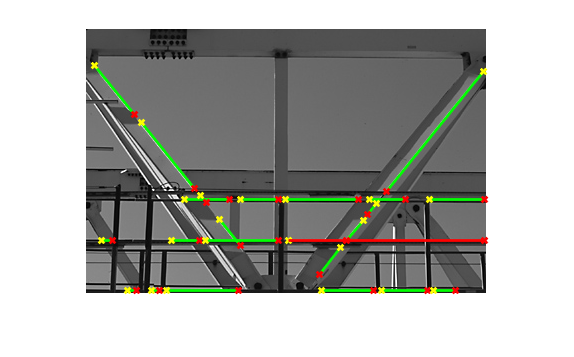

lines = houghlines(BW,theta,rho,P,'FillGap',5,'MinLength',7);
figure, imshow(rotI), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');